%Load dataset
Im = load("tumorData.mat");
Im = Im.data;
size(Im)

ans =    378   473


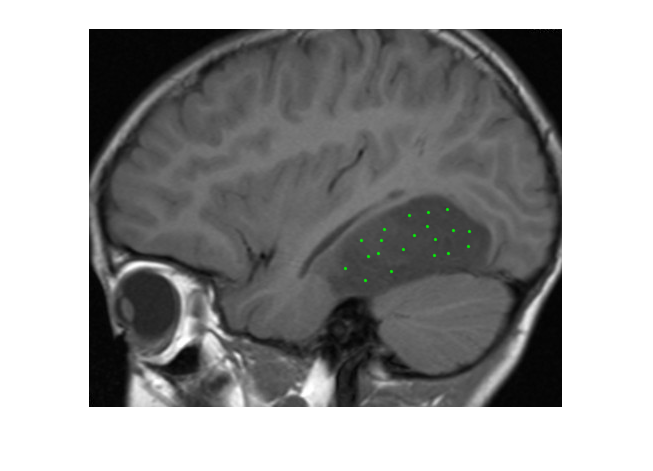

figure();
imshow(Im, [])
hold on;
plot(xSelPoints, ySelPoints, '.g')
hold off;

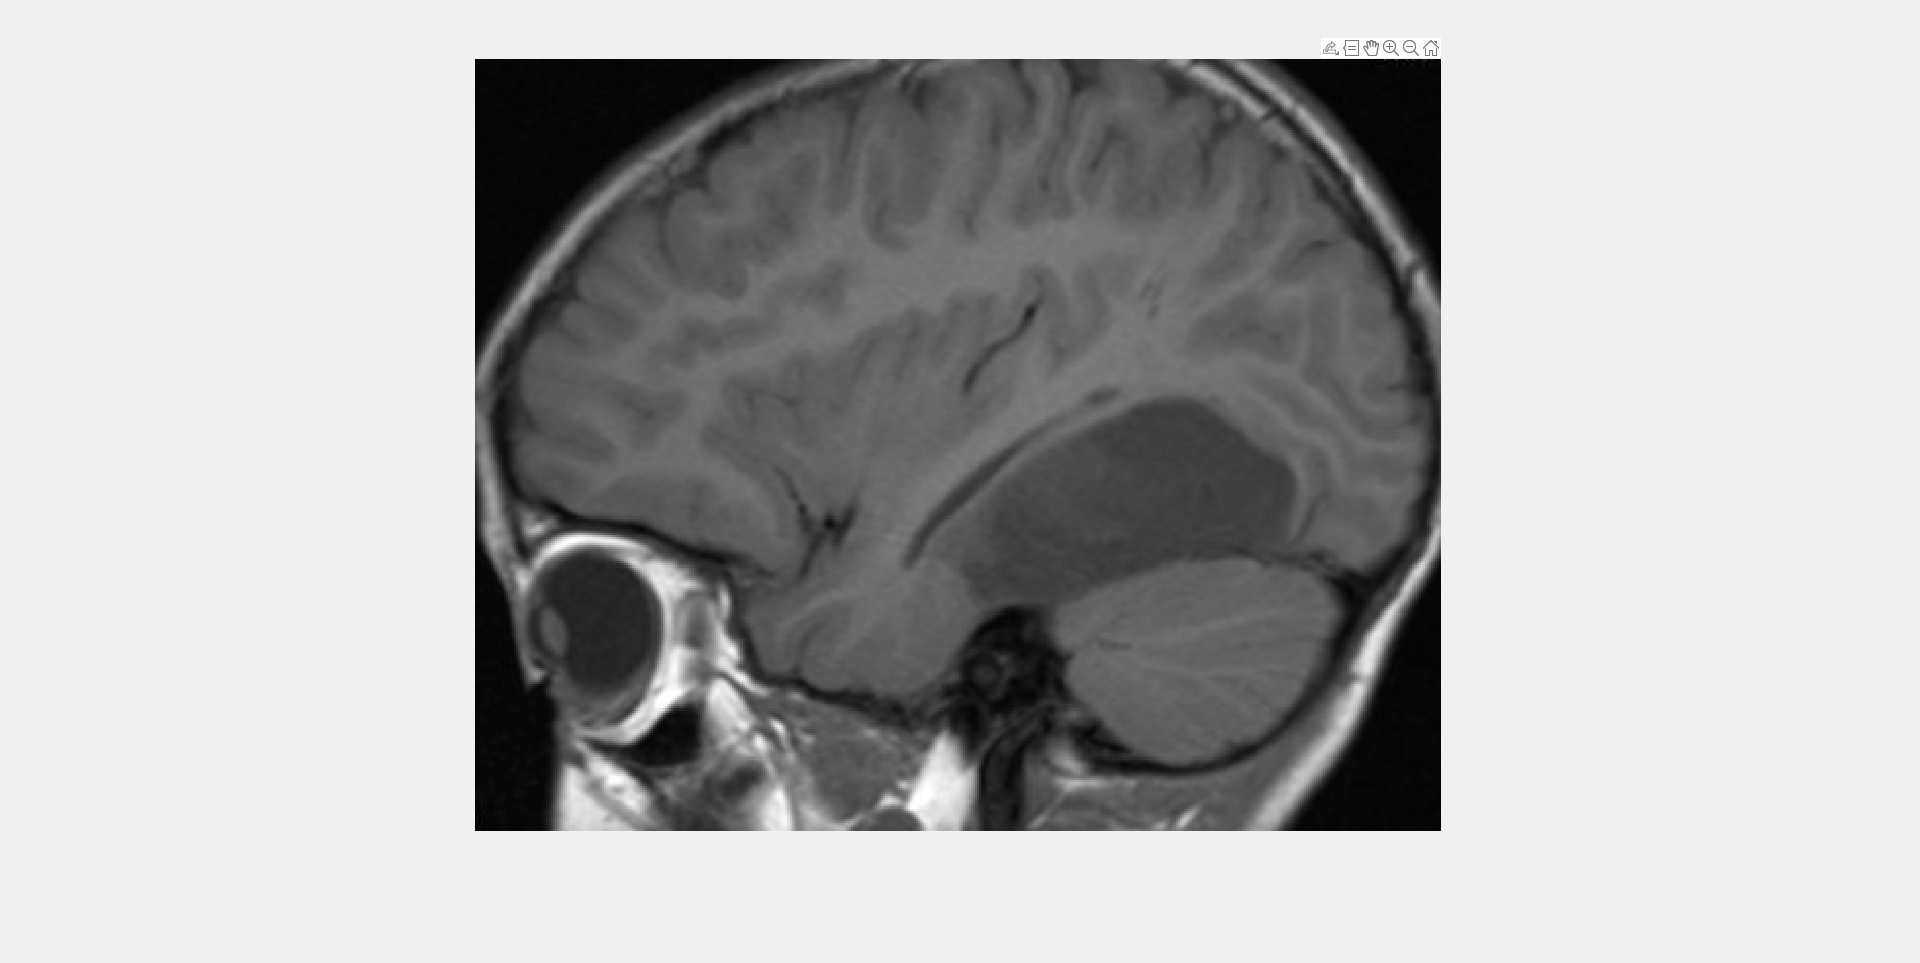

%Select 20 points
[xSelPoints, ySelPoints] = getpts;

%Round the selected image coordinates
xSelPoints = round(xSelPoints);
ySelPoints = round(ySelPoints);

%Calculate the mean and standard deviation of the intensities of selected points
ImSelIntensity = diag(Im(ySelPoints, xSelPoints))

ImSelIntensity =     74
    62
    63
    69
    70
    66
    74
    68
    67
    71


tumorMean = mean(ImSelIntensity)

tumorMean = 66.6000

tumorStd = var(ImSelIntensity)

tumorStd = 22.2526

%Calculate the mean and standard deviation of all image intensities
ImMean = mean(Im(:))

ImMean = 81.6845

ImStd = var(Im(:))

ImStd = 1.7153e+03


%Define the prior probabilities
pi = [0.2 0.8];

%Calculate posterior probabilities
posteriorLab1 = normpdf(Im, tumorMean, sqrt(tumorStd)) * pi(1) ./ (normpdf(Im, tumorMean, sqrt(tumorStd)) * pi(1) ...
    + normpdf(Im, ImMean, sqrt(ImStd)) * pi(2))

posteriorLab1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   

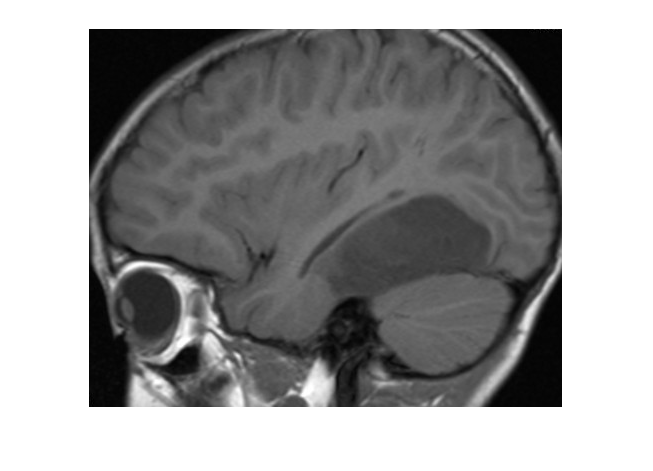


rgb = zeros([size(Im) 3]);
posteriorLab2 = 1 - posteriorLab1;
rgb(:, :, 1) = posteriorLab1 > posteriorLab2;
figure();
imshow(Im, [])

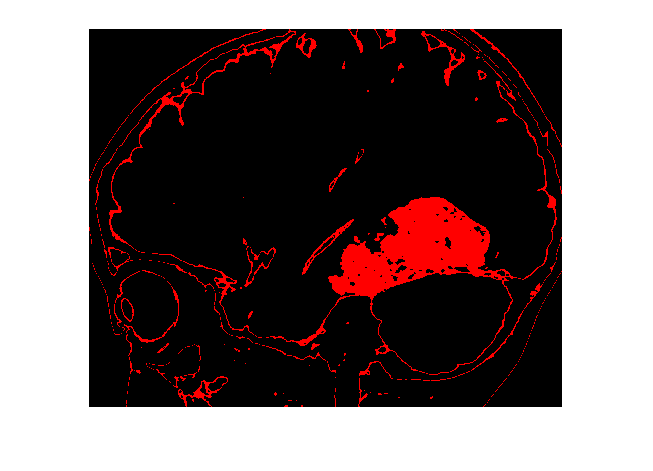

figure();
imshow(rgb, [])